一、

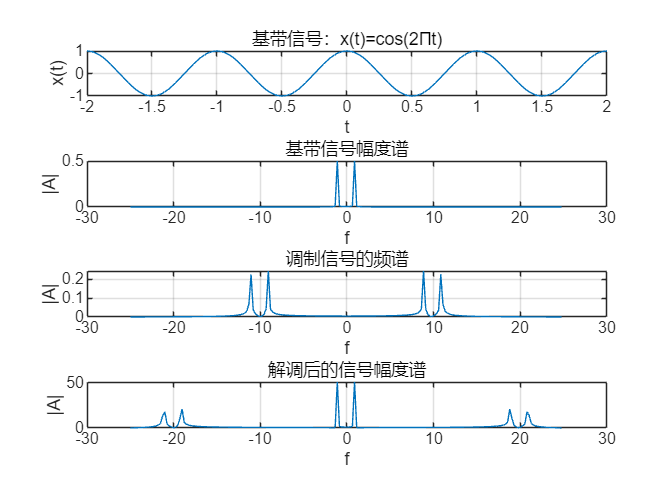

t1=-2:0.02:2;
L=length(t1);
x1=cos(2*pi*t1).*cos(20*pi*t1);
disc=cos(20*pi*t1);

figure(1);
subplot(4,1,1);
plot(t1,cos(2*pi*t1));
xlabel('t');
ylabel('x(t)');
title('基带信号：x(t)=cos(2Πt)');
grid on;

subplot(4,1,2)
ft1=fftshift(fft(cos(2*pi*t1),L));
w=(-L/2:L/2-1)/0.02/L;
plot(w,abs(ft1/L));
xlabel('f');
ylabel('|A|');
title('基带信号幅度谱')
grid on;

subplot(4,1,3)
ft1=fftshift(fft(x1,L));
w=(-L/2:L/2-1)/0.02/L;
plot(w,abs(ft1/L));
xlabel('f');
ylabel('|A|');
title('调制信号的频谱')
grid on;

subplot(4,1,4);
plot(w,abs(fftshift(fft(x1.*disc,L))));
xlabel('f');
ylabel('|A|');
title('解调后的信号幅度谱')
grid on;

解调后的信号大约是原信号cos(2Πt)的1/2，因为调制时，乘以载波cos(20Πt) 后，

调制信号较输入信号在幅度谱上幅值减半，且向左右移频；解调时再次乘以载波cos(20Πt)，

解调信号在幅度谱较调制信号再次减半且移频，在低频率部分叠加，使得解调后的信号较原信号在幅度谱上幅值减半。

而且采样点较少，欠采样，解调后的信号产生频率重叠部分

二、

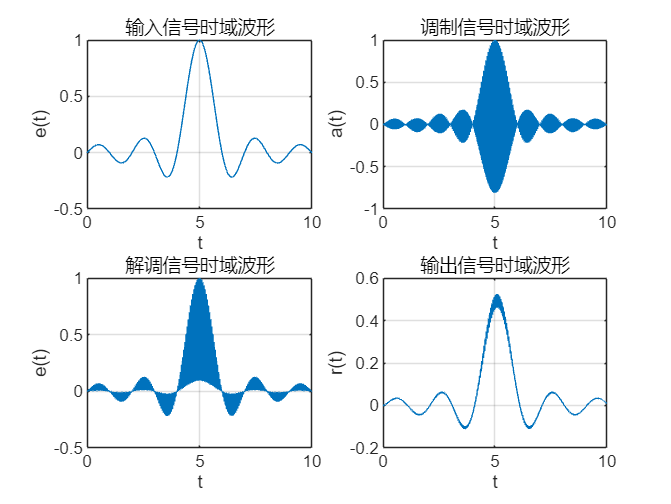

t2=0:0.01:10;
e1=sinc(t2-5);
figure(4);
subplot(2,2,1);
plot(t2,e1);
xlabel('t');
ylabel('e(t)');
title('输入信号时域波形');
grid on;

subplot(2,2,2);
s1=cos(80*pi*t2);
e2=e1.*s1;
plot(t2,e2);
xlabel('t');
ylabel('a(t)');
title('调制信号时域波形');
grid on;

subplot(2,2,3);
e3=e2.*s1;
plot(t2,e3);
xlabel('t');
ylabel('e(t)');
title('解调信号时域波形');
grid on;

subplot(2,2,4);
num=10;
den=[1,10];
sys=tf(num,den);
r=lsim(sys,e3,t2);
plot(t2,r);
xlabel('t');
ylabel('r(t)');
title('输出信号时域波形');
grid on;

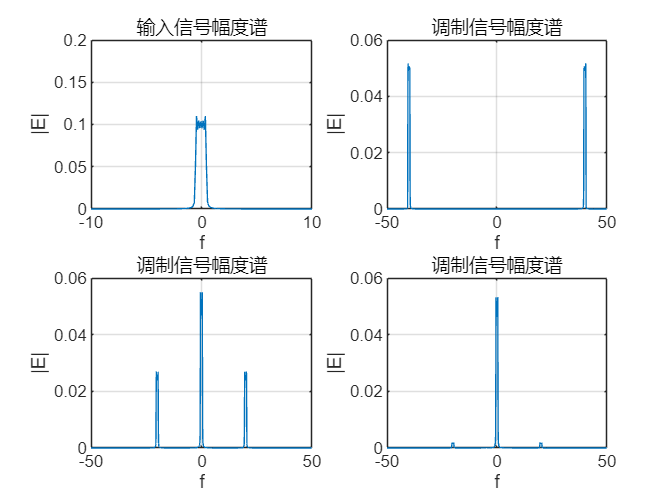


figure(5);
L=length(t2);
w=(-L/2:L/2-1)/L/0.01;
subplot(2,2,1);
f1=fft(e1,L);
ft1=fftshift(f1);
plot(w,abs(ft1/L));
axis([-10 10 0 0.2]);
title('输入信号幅度谱');
xlabel('f');
ylabel('|E|');
grid on;

subplot(2,2,2);
f2=fft(e2,L);
ft2=fftshift(f2);
plot(w,abs(ft2/L));
title('调制信号幅度谱');
xlabel('f');
ylabel('|E|');
grid on;

subplot(2,2,3);
f3=fft(e3,L);
ft3=fftshift(f3);
plot(w,abs(ft3/L));
title('调制信号幅度谱');
xlabel('f');
ylabel('|E|');
grid on;

subplot(2,2,4);
f4=fft(r,L);
ft4=fftshift(f4);
plot(w,abs(ft4/L));
title('调制信号幅度谱');
xlabel('f');
ylabel('|E|');
grid on;

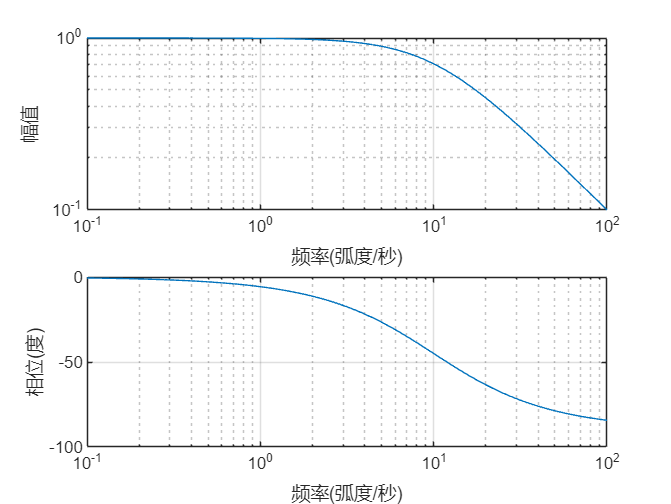


figure(6);
w=logspace(-1,2,500);
freqs(num,den,w);

由图可知，系统函数H(s)是一个低通滤波器，允许低频分量通过，过

滤高频分量其作用是将解调信号频谱波形恢复成原始信号频谱

三、

(1)

dt=0.2

dt = 0.2000

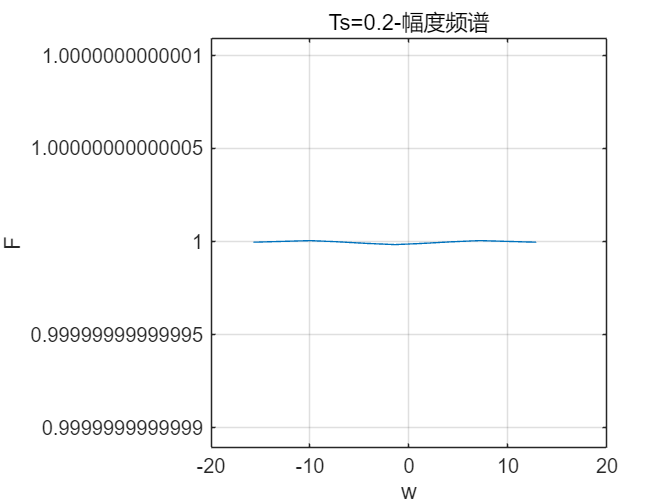

t3=-1:dt:1;
x3=sinc(10*t3);
L=length(t3);
w=2*pi*(-L/2:L/2-1)/L/dt;

f3_1=fft(x3,L);
ft3_1=fftshift(f3_1);

figure(7);
plot(w,abs(ft3_1));
xlim([-20 20]);
xlabel('w');
ylabel('F');
title('Ts=0.2-幅度频谱');
grid on;

(2)

dt=0.05

dt = 0.0500

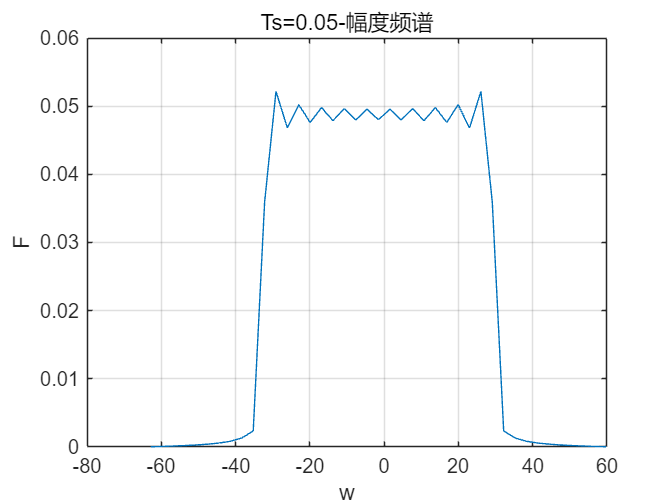

t3=-1:dt:1;
x3=sinc(10*t3);
L=length(t3);
w=2*pi*(-L/2:L/2-1)/L/dt;

f3_1=fft(x3,L);
ft3_1=fftshift(f3_1);

figure(7);
plot(w,abs(ft3_1/L));
xlabel('w');
ylabel('F');
title('Ts=0.05-幅度频谱');
grid on;

由上图可知，采样周期越小，即采样率越大，幅度谱频宽越窄

事实上，奈奎斯特采样定律：当采样频率fs大于信号中最高频率的2倍时(fs>2fmax)，

采样之后的数字信号完整地保留了原始信号中的信息，不发生混叠现象。

原始信号其中最高频率成分是 fmax=5Hz，采样频率 fs ≥ 2fmax=10Hz。

当采样频率较低（Ts=0.2s，fs=5Hz）时，不满足奈奎斯特定律，导致频谱

产生了混叠

当采样频率较高（Ts=0.05s，fs=20Hz）时，满足奈奎斯特定律，频谱图更

加精确，没有明显的混叠效应